**Analisi rete Polblogs**

Ronald Frump è un ricchissimo imprenditore americano che ha deciso di candidarsi come rappresentante di destra alle elezioni presidenziali del 2004.  Dovendo impostare la sua campagna elettorale, Ronald vuole far leva sui blog più influenti. Il suo team di esperti si mette quindi all’opera per scoprire come investire il budget di Ronald per allestire una campagna elettorale che lo porti al successo. Per far ciò, il team misura innanzitutto l'assortatività della rete Polblogs, contenente i link tra i blog di politica americani estratti proprio in quell'anno. 

Il valore dei nodi di Polblogs, infatti, indica l'inclinazione politica nel seguente modo:

-   0 (sinistra o liberali)

-   1 (destra o conservatori)

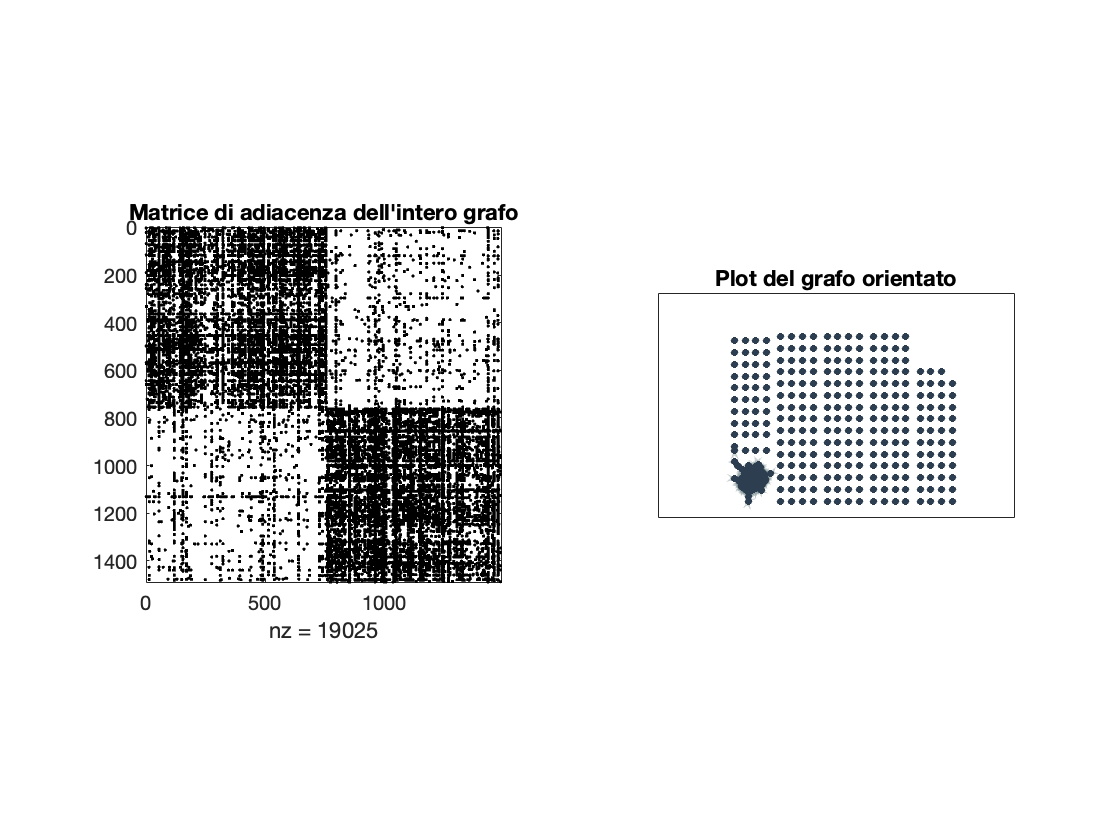

clear 
close all

neutral_color = '#2c3e50';
light_color = '#95a5a6';

load polblogs.mat
A = Problem.A;
clear Problem.A;


tiledlayout(1,2);
nexttile    
spy(A,'k');
title('Matrice di adiacenza dell''intero grafo');

nexttile
G = digraph(A);
plot(G, 'Layout', 'Force', 'NodeColor',neutral_color, 'LineWidth',0.1,'EdgeColor',light_color, 'MarkerSize',3);
title('Plot del grafo orientato');
daspect([1 1 1]);

Estrazione della componente connessa principale della rete

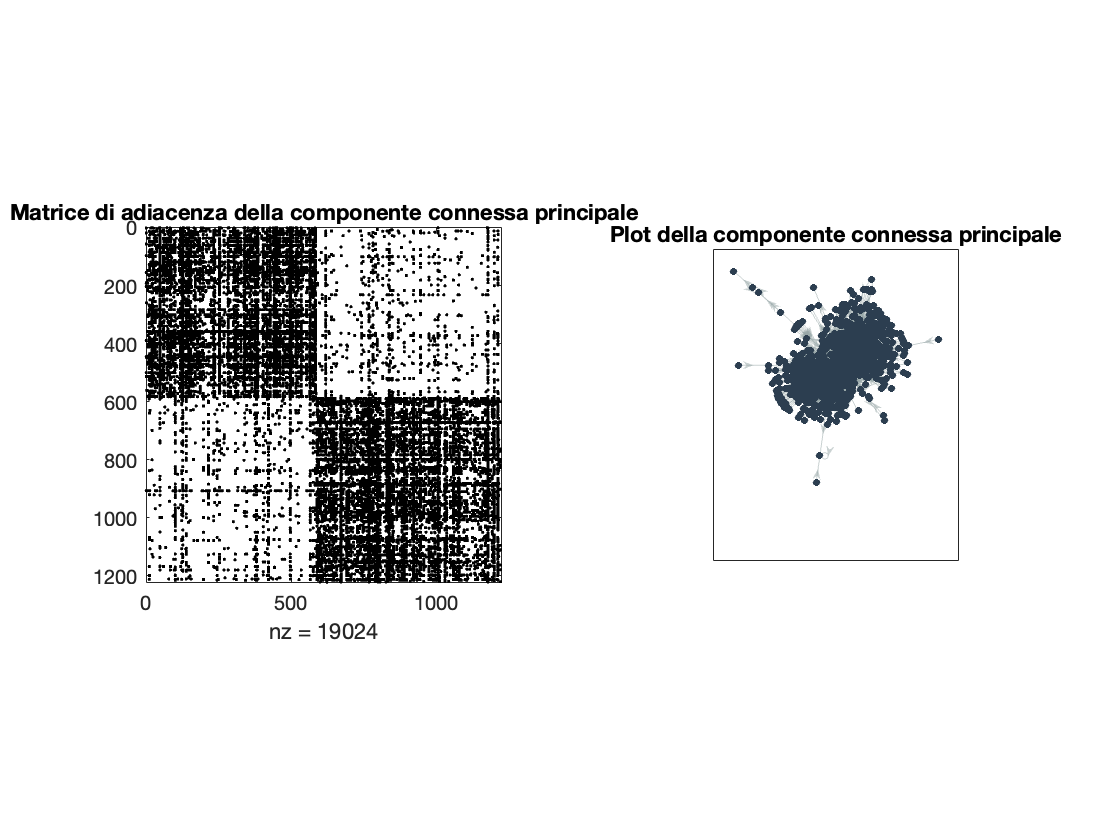

[~,~,membership] = F_connected(A);

nodenames = Problem.aux.nodename;
clear Problem.aux.nodename;

main_component_nodes = find(membership == 1);
sz = size(nodenames,1);
names = strings(sz,1);
for i=1:sz
   names(i) = convertCharsToStrings(nodenames(i,:));
end
nodenames = names(main_component_nodes,1);

B = A(main_component_nodes, main_component_nodes);
GB = digraph(B);
figure();
tiledlayout(1,2);
nexttile    
spy(B,'k');
title('Matrice di adiacenza della componente connessa principale');

nexttile
plot(GB, 'Layout', 'Force', 'NodeColor',neutral_color, 'LineWidth',0.1,'EdgeColor',light_color, 'MarkerSize',3);
title('Plot della componente connessa principale');
daspect([1 1 1]);

**Analisi dell'assortatività della rete:**

La rete risulta essere molto assortativa. Il team di Ronald deduce quindi che i blog di sinistra si citano molto a vicenda e lo stesso vale per i blog di destra. I collegamenti tra blog di fazioni diverse sono invece molto rari. Fatta questa scoperta, Ronald ordina al suo team di individuare i blog conservatori più influenti. La sua idea è infatti quella di allocare un budget pubblicitario più alto sui questi blog, così da mantenere salda la sua posizione tra gli elettori di destra. Con i blog di sinistra, invece, Ronald adotterà una strategia piuttosto diversa.

nodevalues = Problem.aux.nodevalue;
clear Problem.aux.nodevalue;
nodevalues = nodevalues(main_component_nodes,1);

[I,J] = find(B > 0);
s = nodevalues(I);
t = nodevalues(J);

assortativity = F_pearson(s,t)

assortativity = 0.8230

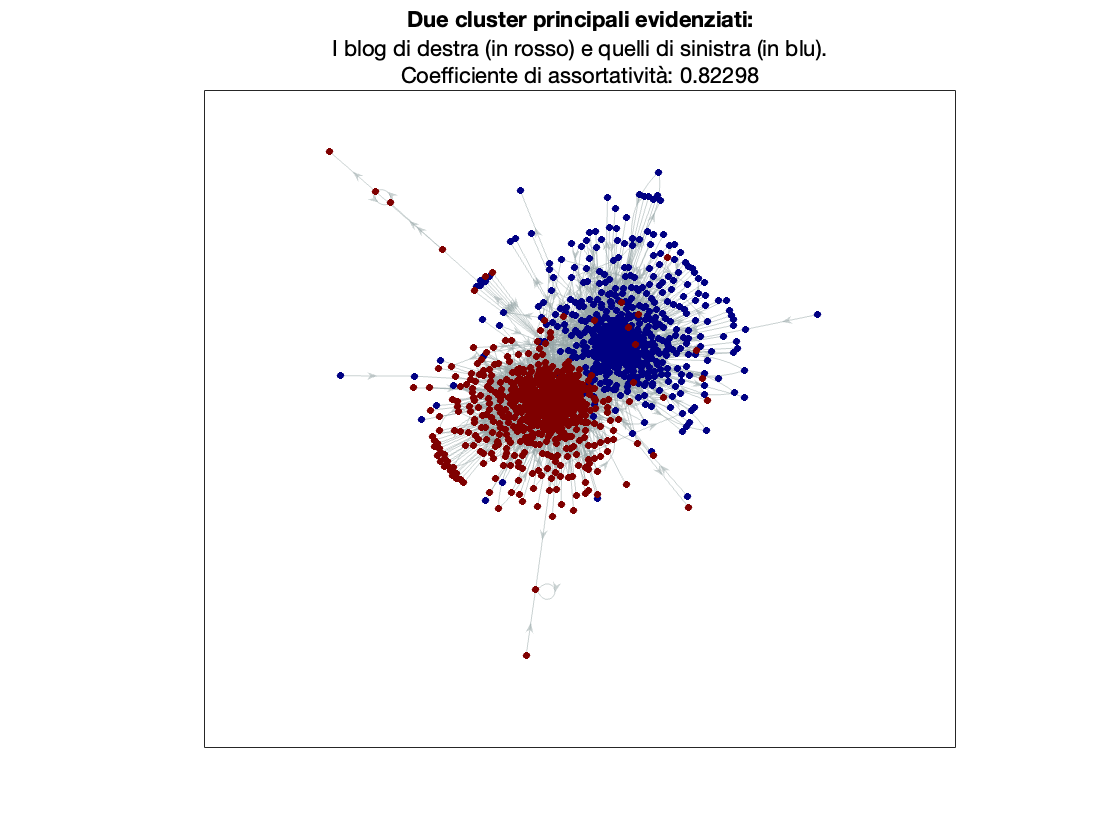

figure;
plot(GB, 'NodeCData', nodevalues,'Layout','force', 'EdgeColor',light_color, 'LineWidth', 0.1, 'MarkerSize',3);
title('Due cluster principali evidenziati:');
subtitle({'I blog di destra (in rosso) e quelli di sinistra (in blu).', 'Coefficiente di assortatività: '+string(assortativity)});
colormap jet;
daspect([1 1 1])

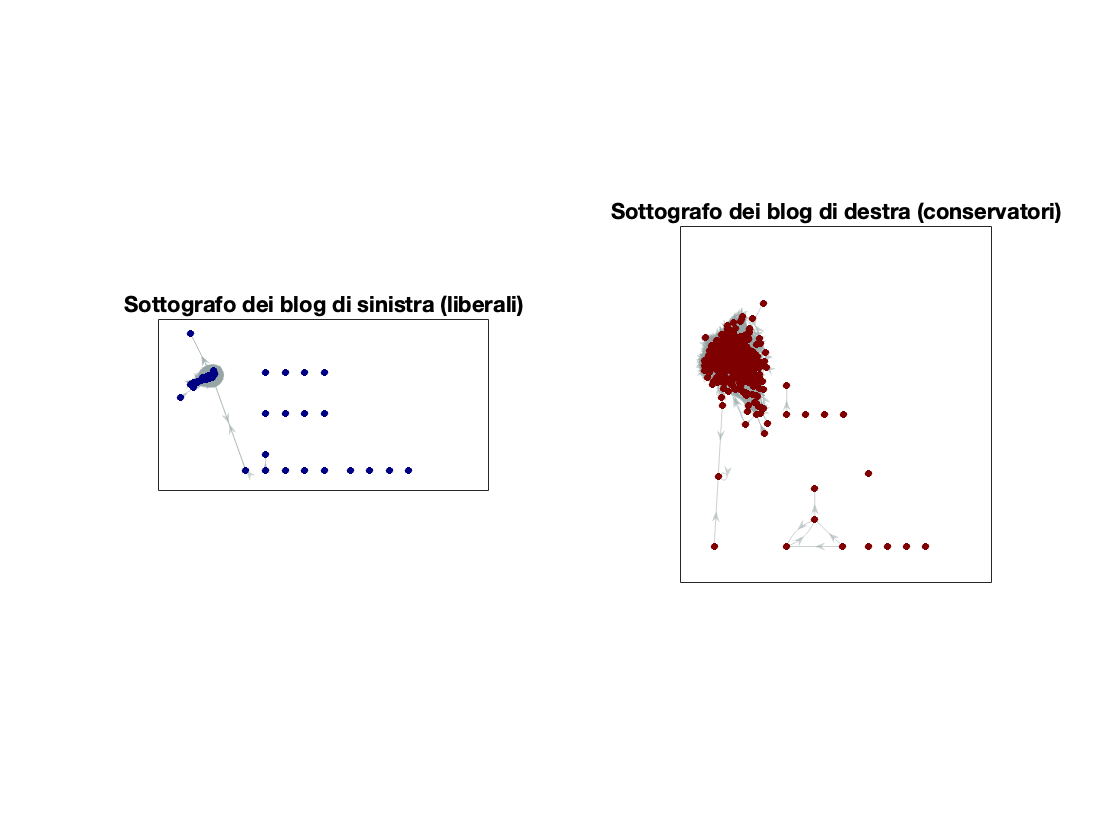


B_liberals = B(nodevalues==0,nodevalues==0);
B_conservators = B(nodevalues==1,nodevalues==1);

liberals_indices = nodevalues==0;
conservators_indices = nodevalues==1;

liberals_names = nodenames(liberals_indices);
conservators_names = nodenames(conservators_indices);

figure();
tiledlayout(1,2);
nexttile
plot(digraph(B_liberals),'NodeColor','#000085', 'Edgecolor',light_color, 'LineWidth',0.1, 'MarkerSize',3);
title('Sottografo dei blog di sinistra (liberali)');
daspect([1 1 1]);
nexttile
plot(digraph(B_conservators),'NodeColor','#7F0000', 'Edgecolor',light_color, 'LineWidth',0.1, 'MarkerSize',3);
title('Sottografo dei blog di destra (conservatori)');
daspect([1 1 1]);

**Calcolo misure di centralità dei grafi dei blog di destra (conservatori, in rosso) e di sinistra (liberali, in blu)**

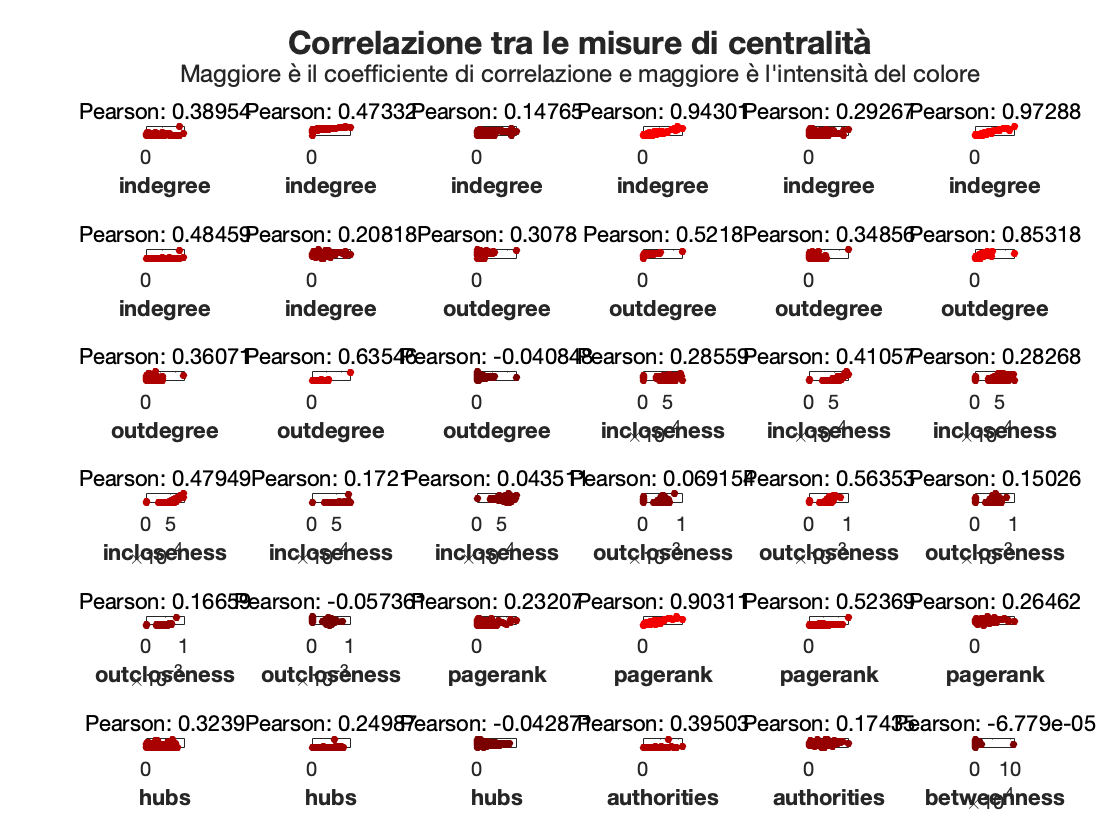

[centrality_scores_conservators, topk_conservators] = F_centrality_analysis(B_conservators, nodenames(conservators_indices), toplot=true, color='r', show_units=true);

topk_conservators

topk_conservators = 12×18 table
                                     top 12 indegree                                      indegree                                     top 12 outdegree                                     outdegree                                    top 12 incloseness                                    incloseness                                   top 12 outcloseness                                    outcloseness                                     top 12 pagerank                                      pagerank                                       top 12 hubs                                          hubs                                       top 12 authorities                                    authorities                                

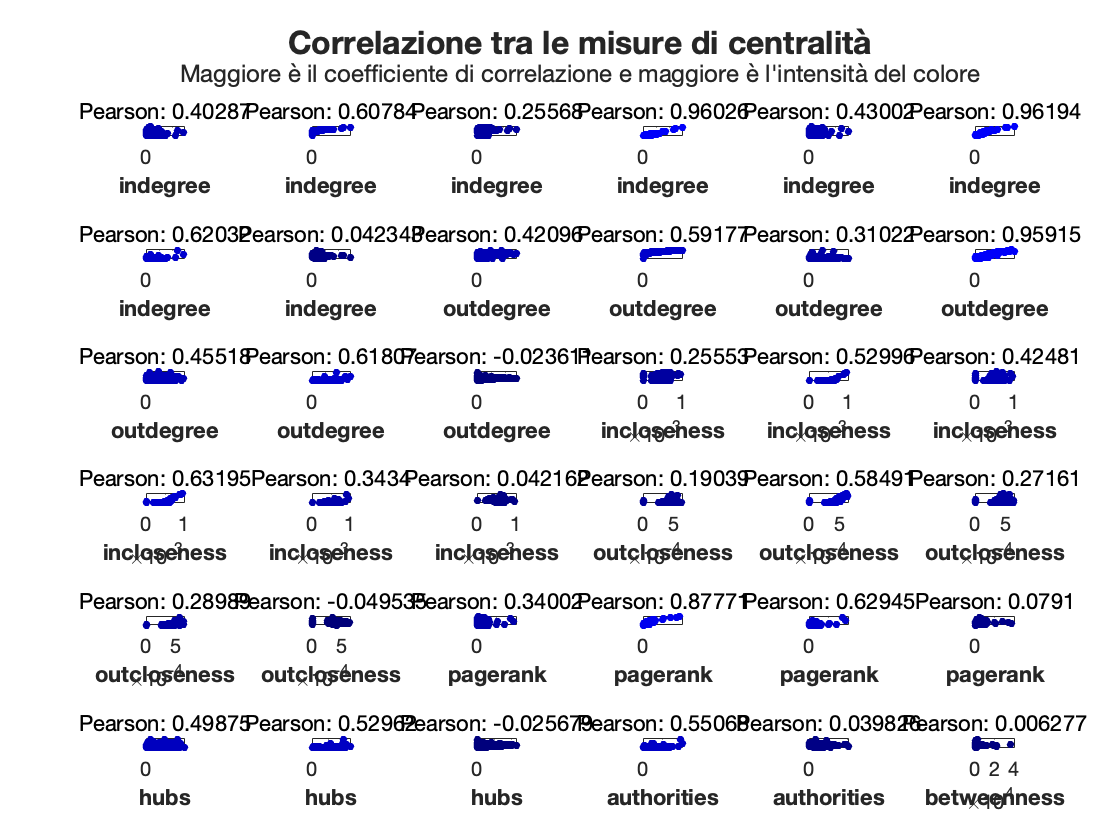

[centrality_scores_liberals, topk_liberals] = F_centrality_analysis(B_liberals, nodenames(liberals_indices), toplot=true, color='b', show_units=true);

topk_liberals

topk_liberals = 12×18 table
                                     top 12 indegree                                      indegree                                     top 12 outdegree                                     outdegree                                    top 12 incloseness                                    incloseness                                   top 12 outcloseness                                    outcloseness                                     top 12 pagerank                                      pagerank                                       top 12 hubs                                          hubs                                       top 12 authorities                                    authorities                                    

**Scelta dei blog conservatori più influenti**

Il team di esperti, eseguendo una analisi della centralità di ciascun nodo, verifica che gli indici di centralità di PageRank, Indegree e authorities sono a due a due piuttosto correlati.

Queste misure consentono di individuare i nodi più popolari all'interno del gruppo dei blog conservatori. Il team suggerisce quindi a Ronald di assegnare un budget direttamente proporzionale a quanto è elevato il punteggio di PageRank e di Katz dei 12 blog più influenti. Osservando la correlazione tra le varie misure infatti, il team si accorge che su questa rete il grado entrante è estremamente correlato con il punteggio di authority, e il punteggio di authority è a sua volta piuttosto correlato con quello di PageRank. Il team di Ronald, conoscendo l'efficacia di quest'ultima misura, decide di privilegiare PageRank rispetto agli altri due indici. Inoltre, il team decide di basarsi anche sul punteggio di Katz perchè permette di individuare i nodi più "popolari" e, almeno in questa rete, non è ridondante rispetto alle altre misure. I top 12 blog individuati dall'indice di Katz, ovvero i più popolari tra gli elettori di destra, saranno quindi quelli con cui il team fisserà delle interviste per infiammare i fan di Ronald. Il team decide poi di selezionare i 12 blog con punteggio PageRank più alto per investire in banner pubblicitari con delle foto del loro capo. In questo modo tra i risultati principali delle loro ricerche gli elettori vedranno sicuramente il volto del candidato presidente.

t1=topk_conservators(:,'top 12 KATZ');
t2=topk_conservators(:, 'top 12 pagerank');
[t1,t2]

ans = 12×2 table
                                       top 12 KATZ                                                                         top 12 pagerank                                  
    __________________________________________________________________________________    __________________________________________________________________________________

    "kausfiles.com                                                                   "    "blogsforbush.com                                                                "
    "andrewsullivan.com                                                              "    "michellemalkin.com                                                              "
    "realclearpolitics.com                                                           "    "instapundit.com                                                                 "
    "drudgereport.com                            

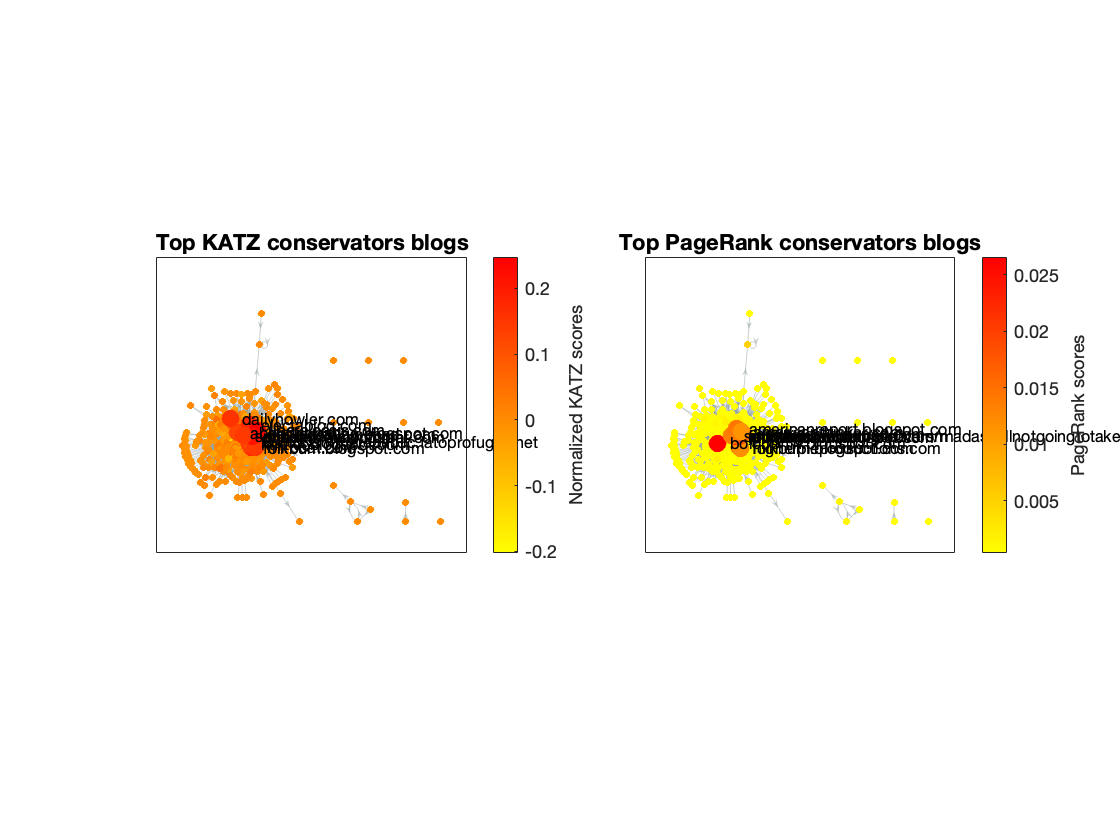

[topk_conservators_katz_scores,topk_conservators_katz_indices] = maxk(centrality_scores_conservators('KATZ'), 12);
NodeLabel = strings(length(conservators_names),1);
NodeLabel(topk_conservators_katz_indices,1) = nodenames(topk_conservators_katz_indices,1);
figure();
tiledlayout(1,2);
nexttile
h = plot(digraph(B_conservators),'NodeLabel', NodeLabel, 'NodeCData', centrality_scores_conservators('KATZ'),'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',light_color,'MarkerSize',3);
highlight(h, topk_conservators_katz_indices, 'MarkerSize',8);
colormap(flipud(autumn))
title('Top KATZ conservators blogs');
c = colorbar;
c.Label.String = 'Normalized KATZ scores';
[topk_conservators_pagerank_scores,topk_conservators_pagerank_indices] = maxk(centrality_scores_conservators('pagerank'), 12);
NodeLabel = strings(length(conservators_names),1);
NodeLabel(topk_conservators_pagerank_indices,1) = nodenames(topk_conservators_pagerank_indices,1);
daspect([1 1 1]);
nexttile
h = plot(digraph(B_conservators),'NodeLabel', NodeLabel, 'NodeCData', centrality_scores_conservators('pagerank'),'NodeLabelColor','k', 'Layout', 'Force', 'ArrowSize',3,'EdgeColor',light_color,'MarkerSize',3);
highlight(h, topk_conservators_pagerank_indices, 'MarkerSize',8);
colormap(flipud(autumn))
title('Top PageRank conservators blogs');
c = colorbar;
c.Label.String = 'PageRank scores';
daspect([1 1 1]);

**Analisi blogs Liberali**

Per quanto riguarda i blog liberali, Ronald chiede al suo team di esperti di scoprire diverse caratteristiche. In particolare, Ronald vuole sapere se sono presenti sottogruppi tra questi blog, così da poterli studiare singolarmente e sviluppare una strategia apposita per ciascuno.

Il team di esperti, quindi, calcola innanzitutto il coefficiente di clustering dell'intera rete dei blog liberali per farsi una prima idea sulla presenza di clusters locali o globali.

[nComponents,sizes,membership] = F_connected(B_liberals);

main_component_nodes = find(membership == 1);

B_liberals_connected = B_liberals(main_component_nodes, main_component_nodes);
liberals_connected_indices = liberals_indices(main_component_nodes);
liberals_connected_names = liberals_names(liberals_connected_indices);


[C,C_WattsSgrogatz,C_Newman] = F_clustering(B_liberals_connected);
C_WattsSgrogatz

C_WattsSgrogatz = 0.4276

C_Newman

C_Newman = 0.3084

Osservando che il coefficiente di clustering a livello locale è più alto di quello a livello globale, il team suggerisce a Ronald di usare le sue risorse per screditare i singoli blog che hanno un coefficiente di clustering più basso. Come osservato da Mark Granovetter infatti, tali nodi sono quelli in presenza dei quali si notano buchi strutturali nella rete e sono quindi fondamentali per la diffusione di informazioni. Nella pratica si osserva che la maggior parte dei blog individuati con questa tecnica sono nodi periferici, di conseguenza il team decide di calcolare i nodi con beetweenness più elevata, in quanto questa misura di centralità esprime un concetto molto simile. La betweenness misura infatti quanto un nodo è un buon intermediario, ma ha il vantaggio di tenere in considerazione anche gli scambi di informazioni "a lungo raggio", ovvero tra nodi distanti nella rete.

I blog con maggior beetwenness sono decisamente più centrali nel grafo rispetto a quelli con basso clustering, di conseguenza il team suggerisce a Ronald di screditare questi ultimi.

[smallest_clustering_values, smallest_clustering_indices] = mink(nonzeros(C), 5);
smallest_clustering_nodes = liberals_names(smallest_clustering_indices);
t1 = table(smallest_clustering_nodes);
t2 = table(smallest_clustering_values);
[t1,t2]

ans = 5×2 table
                                smallest_clustering_nodes                                 smallest_clustering_values
    __________________________________________________________________________________    __________________________

    "blog.kenlan.net                                                                 "             0.038462         
    "scoobiedavis.blogspot.com                                                       "             0.052632         
    "bartcop.com                                                                     "             0.090476         
    "elissa.typepad.com                                                              "             0.090909         
    "fuckthisblog.blogspot.com                                                       "             0.095238         


names = strings(size(C));
names(smallest_clustering_indices,1) = liberals_names(smallest_clustering_indices,1);
figure();
tiledlayout(1,2);
nexttile
p=plot(digraph(B_liberals_connected),'MarkerSize',3, 'NodeCData', C,'NodeLabel',names, 'Layout','Force','EdgeColor',light_color);
highlight(p, smallest_clustering_indices,'MarkerSize',10)
title('Blogs con coefficiente di clustering più basso');
c = colorbar;
c.Label.String = 'Coefficiente di clustering';
colormap(winter);
daspect([1 1 1]);
nexttile
[scores,~] = F_centrality_analysis(B_liberals_connected,liberals_connected_names, centrality_indices="betweenness"); %esempio di uso di F_centrality_analysis per calcolare solo alcune misure di centralità
[largest_betw_values, largest_betw_indices] = maxk(scores('betweenness'), 5);
names = strings(size(C));
names(largest_betw_indices,1) = liberals_connected_names(largest_betw_indices,1);
largest_betw_liberal_blogs = names(largest_betw_indices,1);
t1 = table(largest_betw_liberal_blogs);
t2 = table(largest_betw_values);
[t1 t2]

ans = 5×2 table
                                largest_betw_liberal_blogs                                largest_betw_values
    __________________________________________________________________________________    ___________________

    "atease.blogspot.com                                                             "           36600       
    "dailyhowler.com                                                                 "           22081       
    "nationalreview.com/frum/frum-diary.asp                                          "           21666       
    "livejournal.com/users/hoptkov                                                   "           18727       
    "lefti.blogspot.com                                                              "           17542       


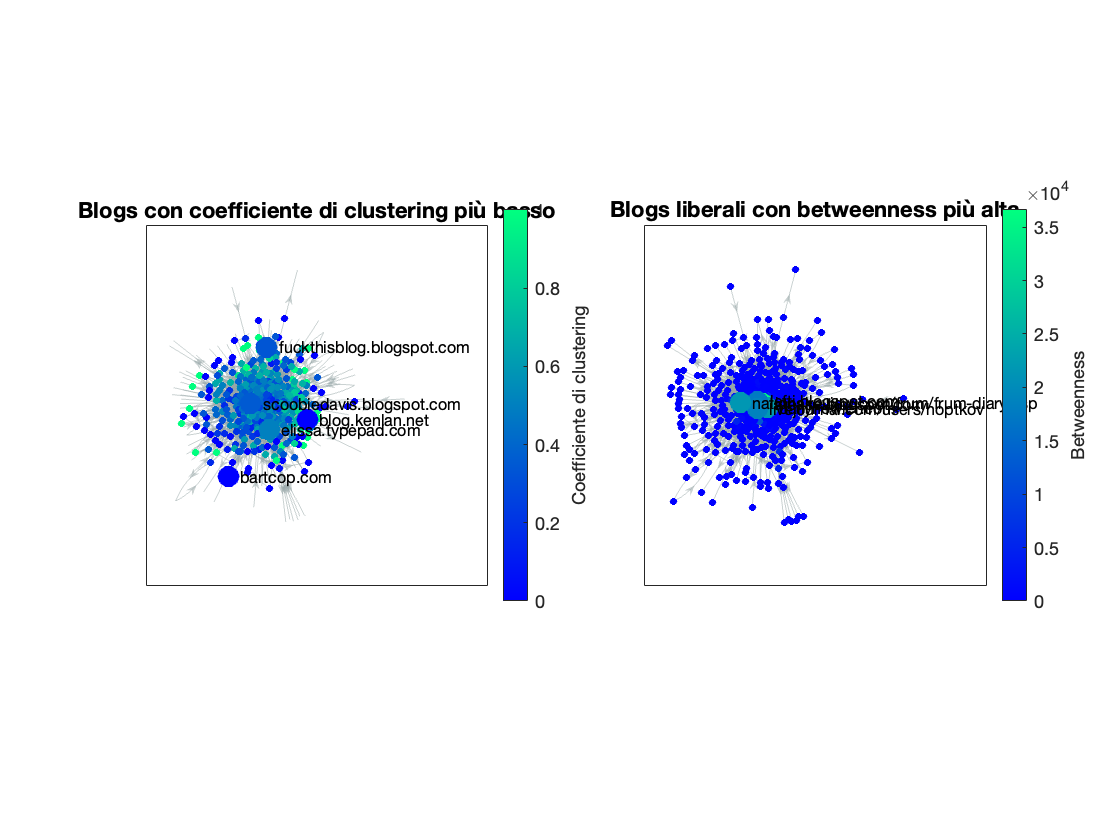

p=plot(digraph(B_liberals_connected),'MarkerSize',3, 'NodeCData', scores('betweenness'),'NodeLabel',names, 'Layout','Force','EdgeColor',light_color);
highlight(p, largest_betw_indices,'MarkerSize',10)
title('Blogs liberali con betweenness più alta');
c = colorbar;
c.Label.String = 'Betweenness';
colormap(winter);
daspect([1 1 1]);

**Clusters & strutture Meso-scala**

Infine, il team di esperti individua le sottocommunity di blog liberali, come richiesto da Ronald, sfruttando il metodo spettrale di community detection e l'algoritmo di Louvain. Il team, inoltre, cerca di individuare la presenza di strutture core-periphery.

B_liberals_connected_symm = (B_liberals_connected+B_liberals_connected')/2;
d = sum(B_liberals_connected_symm,2);
M = B_liberals_connected_symm - d*d' / sum(d); %Modularity Matrix
[v,lambda] = eigs(M, 1)

v =     0.0237
    0.0144
   -0.0017
   -0.0017
    0.0033
   -0.0075
    0.0335
    0.0282
    0.0127
    0.0081


lambda = -16.1282

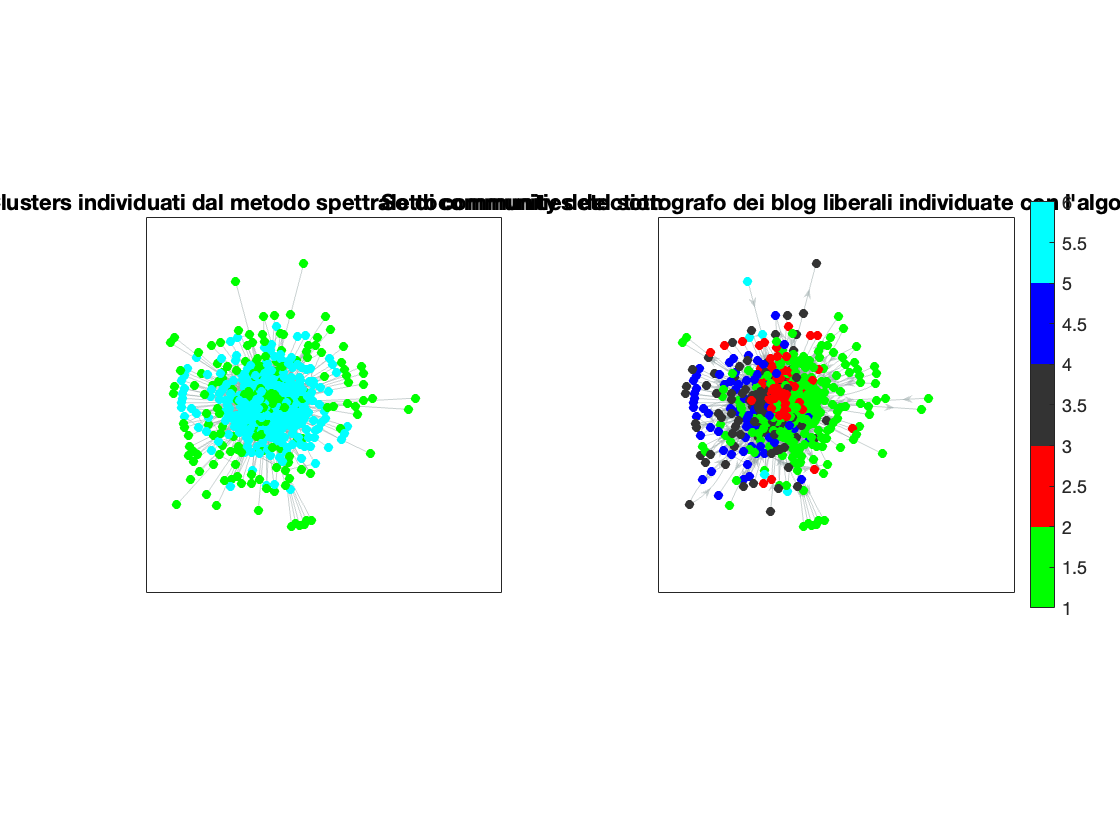

negatives = find(v<0);
NodeCData = ones(length(v),1);
NodeCData(negatives) = 0;
figure();
tiledlayout(1,2)
nexttile
plot(graph(B_liberals_connected_symm), 'NodeCData',NodeCData,'EdgeColor',light_color, 'Layout','Force', 'MarkerSize', 4);
title('Clusters individuati dal metodo spettrale di community detection');
daspect([1 1 1]);

nexttile
[v,m] = F_louvain(B_liberals_connected, 0.9);
plot(digraph(B_liberals_connected), 'NodeCData', v, 'Layout','Force','EdgeColor',light_color,'MarkerSize', 4);
map = [0 1 0
    1 0 0
    0.2 0.2 0.2
    0 0 1
   0 1 1];
colormap(map);
colorbar
title('Sottocommunities del sottografo dei blog liberali individuate con l''algoritmo di Louvain');
daspect([1 1 1]);

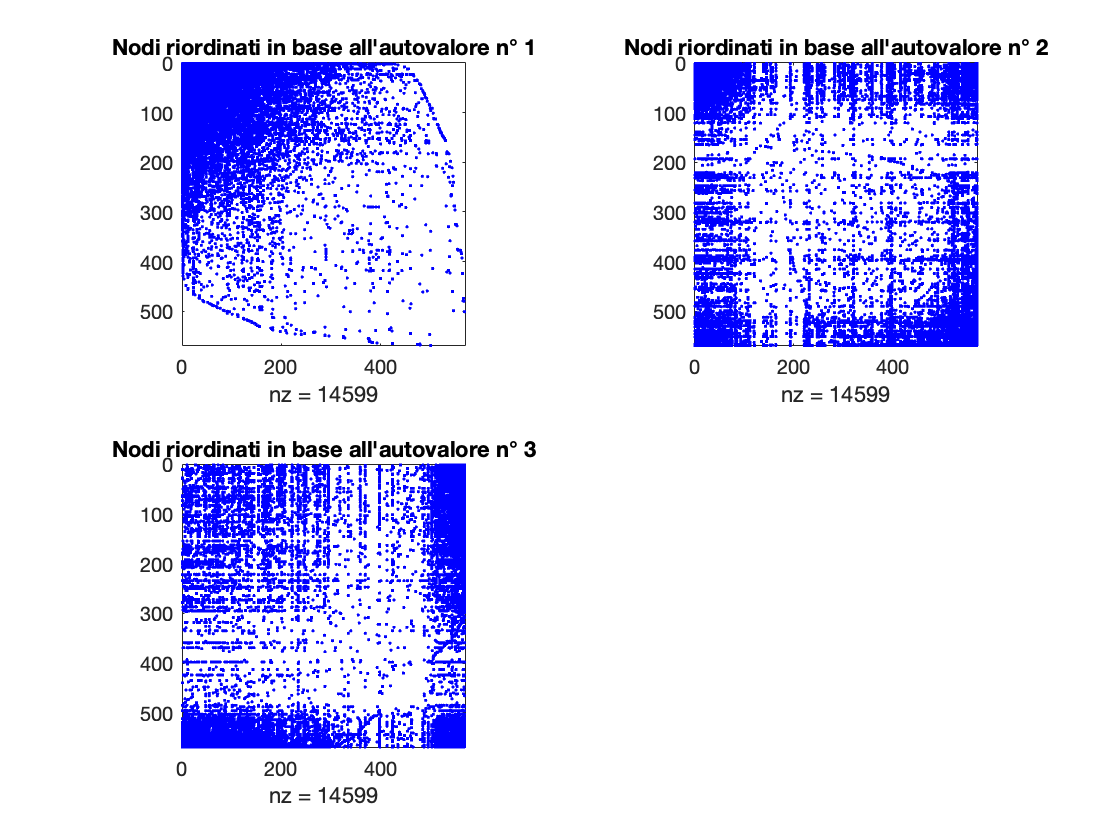

[~,~] = F_spectral_core_periphery(B_liberals_connected,3);

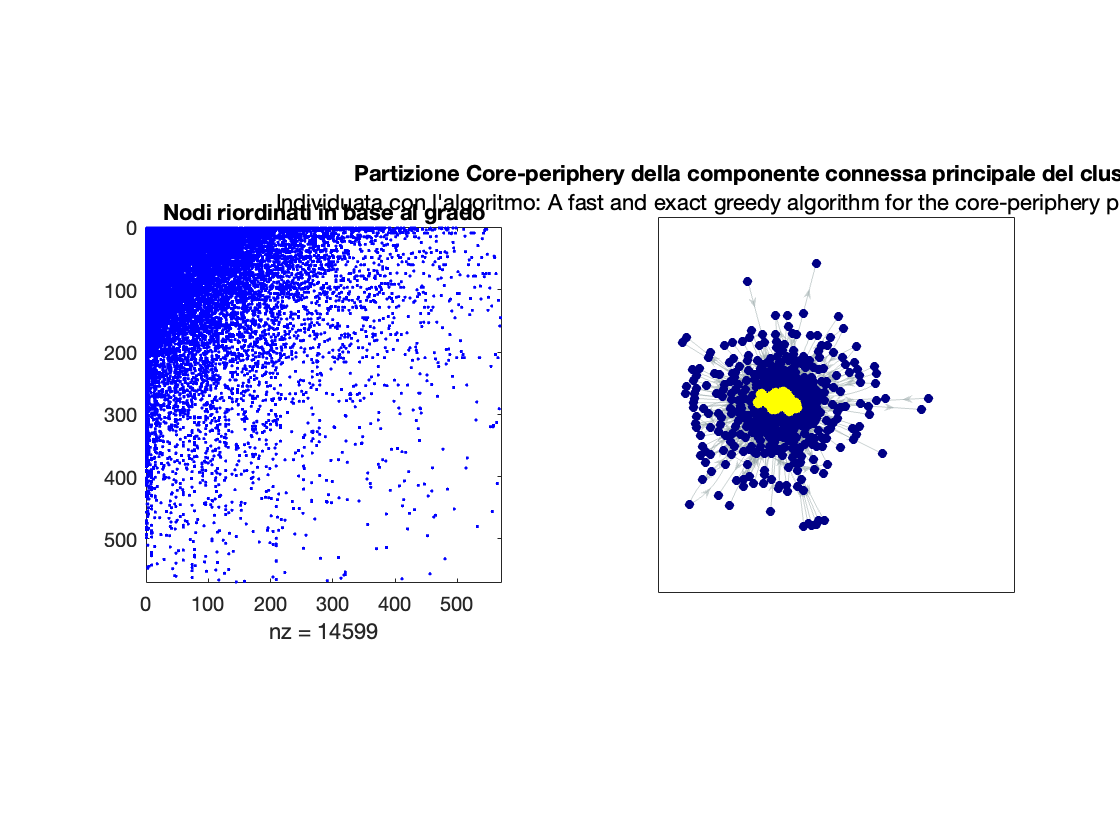

[B_reordered, S, ~] = F_core_periphery_greedy(B_liberals_connected);
figure();
tiledlayout(1,2)
nexttile
spy(B_reordered,'b');
title('Nodi riordinati in base al grado');
nexttile
liberals_connected_names = liberals_names(liberals_connected_indices);
NodeLabel = strings(length(liberals_connected_names),1);
p = plot(digraph(B_liberals_connected),'MarkerSize',4,'NodeColor','#000085','NodeLabel',NodeLabel,'Layout','Force','Edgecolor',light_color);
highlight(p, S','MarkerSize',5,'NodeColor','yellow');
title('Partizione Core-periphery della componente connessa principale del cluster dei blog liberali');
subtitle('Individuata con l''algoritmo: A fast and exact greedy algorithm for the core-periphery problem. D. Fasino, F. Rinaldi');
daspect([1 1 1])

table(liberals_connected_names(S,1),'VariableNames', {'Core liberal blogs'})

ans = 48×1 table
                                    Core liberal blogs                                
    __________________________________________________________________________________

    "dailyhowler.com                                                                 "
    "atease.blogspot.com                                                             "
    "stagefour.typepad.com/commonprejudice                                           "
    "lefti.blogspot.com                                                              "
    "truedemocrat.blogspot.com                                                       "
    "denisdekat.com                                                                  "
    "bluestateredstate.blogspot.com                                                  "
    "contrapositive.blogspot.com                                                     "
    "nationalreview.com/frum/frum-diary.asp                                   

**Scale free e Power Law**

Avendo lavorato duramente, il team di Ronald vuole accertarsi che le analisi svolte saranno utili anche per il futuro. Per questo motivo vuole verificare che la forma della rete dei blog rimanga simile man mano che questi aumentano in numero con il passare degli anni.

 Il team decide quindi di effettuare un'ultima analisi per verificare che la rete su cui ha lavorato sia Scale Free. Per farlo il team calcola la distribuzione dei gradi dei nodi e la ccdf e si accorge che sia la prima che la seconda sono approssimabili con una retta, quindi la legge di potenza è rispettata.

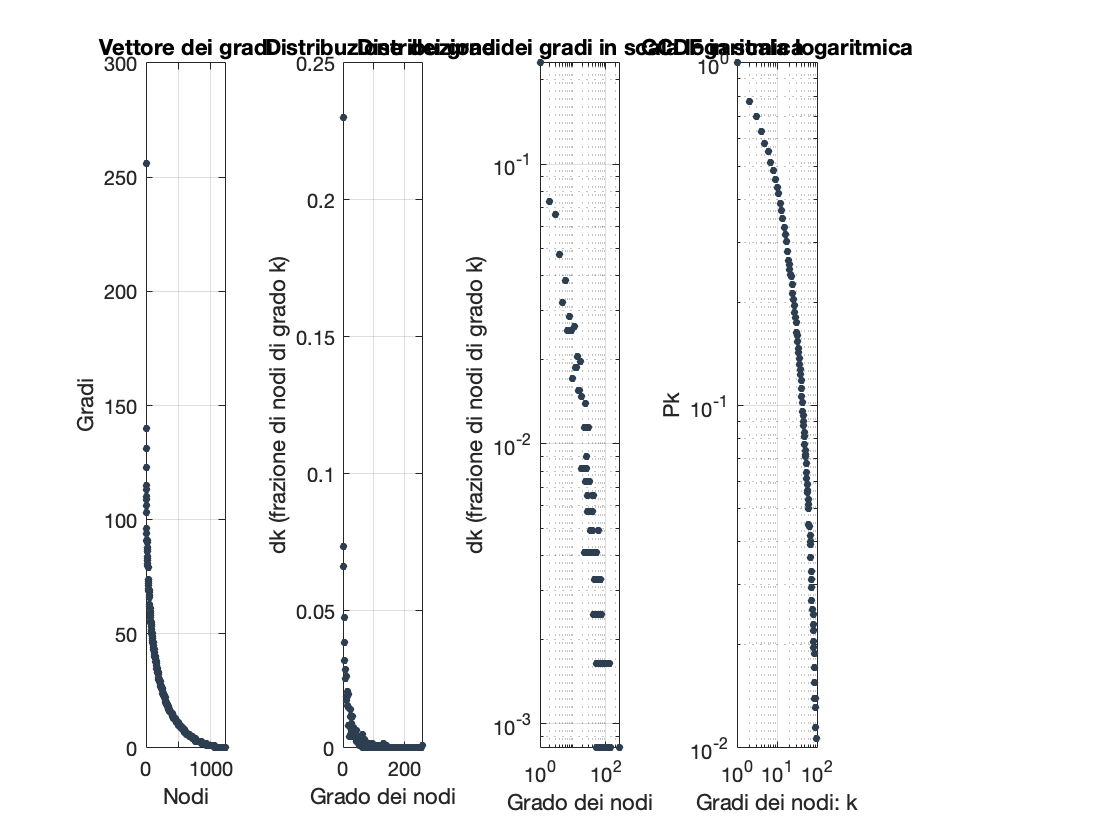

d = sum(B,2);
[~,~] = F_distribution_analysis(B);

**Confronto con Rete Casuale della stessa dimensione della componente connessa principale di Polblogs**

Essendo Ronald molto diffidente, il team di esperti mette a confronto la rete analizzata con un grafo casuale ER di pari dimensioni per mostrargli come l'analisi condotta sia basata su proprietà reali e non su casualità matematiche. La distribuzione dei gradi non segue infatti la Power Law sul grafo casuale, ma ha la forma tipica di una distribuzione di Poisson. Il coefficiente di clustering dei nodi del grafo ER è inoltre molto più basso di quello dei nodi della rete Polblogs. Ronald non capisce come tutte queste nozioni possano essere rilevanti per lui, ma vedendo il team sfinito ed essendo soprattutto ora di pranzo, decide di approvare il budget e la strategia elettorale che gli è stata proposta.

d_avg = mean(d,1)

d_avg =    (1,1)      15.6211


n = (size(B,1));
p = d_avg / (n-1)

p =    (1,1)       0.0128


p>log(n)/n %regime connesso

ans = sparse logical
   (1,1)      1


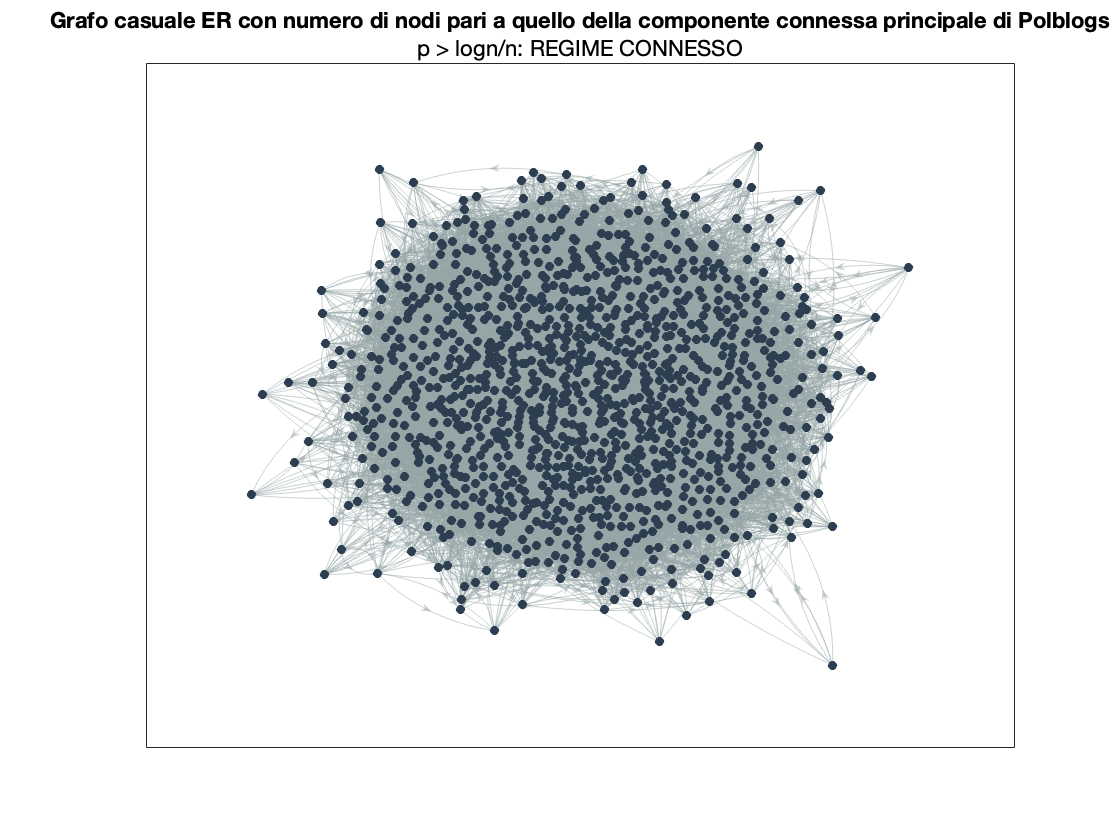


er = G_er(size(B,1), p);

figure();
plot(digraph(er),'MarkerSize',4,'NodeColor',neutral_color,'Layout','Force','Edgecolor',light_color);
title('Grafo casuale ER con numero di nodi pari a quello della componente connessa principale di Polblogs');
subtitle('p > logn/n: REGIME CONNESSO');

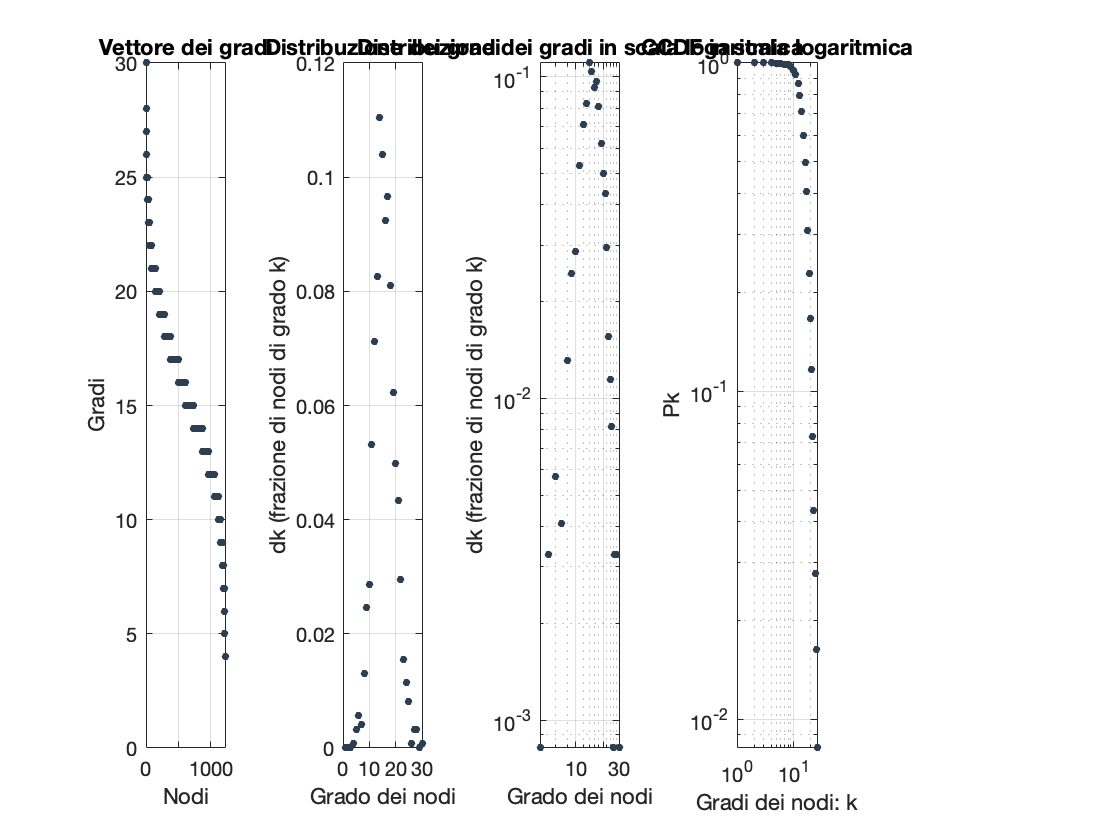

[~,~] = F_distribution_analysis(er);


[C_er,Cws_er,CN_er] = F_clustering(er);
Cws_er

Cws_er = 0.0125

CN_er

CN_er = 0.0125


[C_B,Cws_B, CN_B]=F_clustering(B);
Cws_B

Cws_B = 0.3600

CN_B

CN_B = 0.2260

C_B(isnan(C_B))=0;
table(sort(C_B,'descend'),sort(C_er,'descend'),'VariableNames',{'Coefficienti di clustering di B', 'Coefficienti di clustering del grafo casuale'})

ans = 1222×2 table
    Coefficienti di clustering di B    Coefficienti di clustering del grafo casuale
    _______________________________    ____________________________________________

                   1                                          0.1                  
                   1                                     0.083333                  
                   1                                     0.076923                  
                   1                                     0.060606                  
                   1                                     0.060606                  
                   1                                     0.058333                  
                   1                                     0.055556                  
                   1                                     0.054945                  
                   1                                     0.054945       